# 条带模式合成孔径雷达图像成像

本例子用于展示如何采用线性调频连续波信号(LFM)进行条带模式合成孔径雷达(SAR)成像系统建模。SAR是一种侧视机载"雷达，其可实现的横向距离分辨率比实际孔径雷达高得多。使用SAR生成的图像有其自身的优势，相对于使用被动传感器(相机)的传统成像系统相比，被动成像依赖环境光线获取图像，SAR不存在这个问题。由于使用了主动传感器，该系统能够提供无视雪、雾、雨等各种场景的全天候性能。此外，系统选取不同的载波频率如L，S或者C波段可以根据不同的穿透深度分析地下的不同地层。因为SAR的分辨率是基于信号和天线的参数配置决定，所以成像分辨率可以比视觉成像系统高的多。使用条带模式，本例子呈现一个距离徙动算法[1]和近似反向投影算法[2]来对静止目标进行成像。为了降低计算复杂度，选择了反投影算法的近似形式[3].线性调频连续波(LFM)提供了在低功率发射下大时宽带宽积的优势，使其尤其适合在机载系统中使用。

## 合成孔径雷达成像

SAR生成一个二维图像。飞行方向称为**横向距离方向(cross-range)**或**方位角方向(azimuth direction)**，天线视向(宽侧)的方向与飞行路径正交，称为**交叉轨道方向(cross-track)**或**距离方向(range direction)**。在数据采集的窗口期，这两个方向提供了天线波束宽度范围内区域生成图像的维度基础。**交叉轨道/距离方向**是**脉冲的传播方向.**这个方向提供了沿飞行路径的过程中对目标的倾斜距离.目标反射的每个脉冲的能量必须在接收后进行处理(为了距离测量和分辨率)。横向距离方向或方位角方向是飞行路径的方向，在这个方向上对整个飞行路径中接收到的脉冲信号整体进行处理，以达到测量指标要求的分辨率是非常有意义的。在两个方向上正确地聚焦意味着在**距离**和**横向距离**方向上成功地生成图像。这样就要求天线的波束宽度足够宽，以保证在平台沿其轨迹移动时，目标能被长时间的照射。这样会得到更多的相位信息进行相干积累。

使用SAR时经常遇到的关键术语是:

- **横向距离(方位角)**:该参数定义了雷达平台沿飞行路径的距离。

- **距离**:该参数定义了与雷达平台飞行路径正交的距离。

- 快时间:定义每个脉冲运行的时间。

- 慢时间:该参数定义了横向范围的时间信息。慢时间通常定义了脉冲沿飞行路径传输的时间的实例

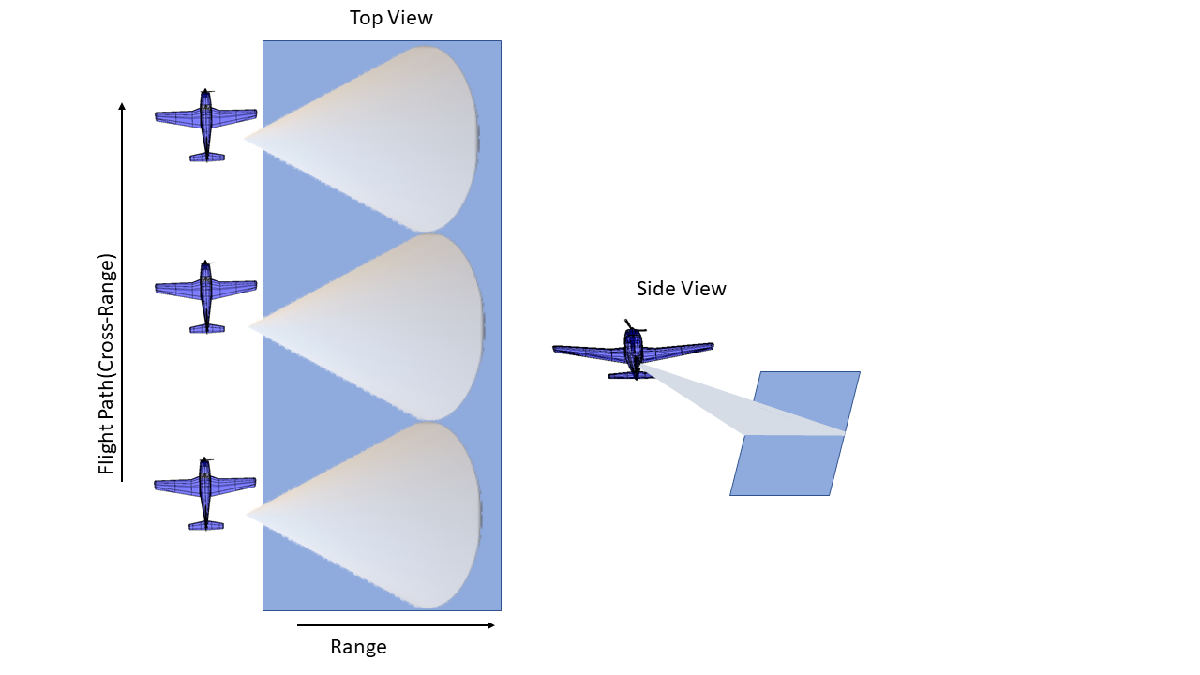

## 雷达的参数配置

考虑到SAR运行在C波段载波频率4GHz并且发射信号带宽50MHz.这个带宽的距离分辨率为3m.雷达系统采集与平台运动方向正交的数据，如图所示。接收到的信号是传输信号的延迟复制。延迟响应一般是目标和平台之间的倾斜距离。对于一个SAR系统来说，由于平台的飞行路径正交与天线的波束方向，因此斜距将会随着时间的变化而变化。下一节我们将专注于发射波形的参数定义。线性扫频信号带宽是基于距离分辨率决定的。

设置光速的物理常量

clear;clc;close all;
c = physconst('LightSpeed');

设置SAR的中心频率

fc = 4e9;

设置期望的距离分辨率和横向距离分辨率为3m

rangeResolution = 3;                            %垂直飞行方向的距离分辨率
crossRangeResolution = 3;                       %横向距离方向(飞行方向)的分辨率

信号带宽参数可以从期望的距离分辨率计算得到               

bw = bw2range(rangeResolution,c);

在SAR系统中(脉冲重复频率)PRF具有双重含义。PRF不仅决定了最大不模糊距离，同时也是横向距离的采样频率。如果PRF太低，则具有较高的不模糊距离，但是脉冲的间隔太长导致特定区域的脉冲太少。与此同时，如果PRF太高，则横向距离采样率足够但是牺牲了距离方向。因此，**PRF应小于多普勒频率的两倍(按道理应该是大于目标多普勒频率的两倍吧？)**，并应满足最大不模糊范围标准

prf = 1000;                                     %脉冲重复频率
aperture = 4;                                   %天线孔径 单位m
tpd = 3*10^-6;                                  %脉冲时间宽度
fs = 120e6;                                     %采样率120Mhz，或者表达频率

配置雷达的线性调频信号

waveform = phased.LinearFMWaveform('SampleRate',fs, 'PulseWidth', tpd, 'PRF', prf,...
    'SweepBandwidth', bw);

假设飞机的飞行速度为100m/s，飞行时间为4秒.

speed = 100;                                                            %设置飞行速度
flightDuration = 4;                                                     %设置飞行时间
radarPlatform  = phased.Platform('InitialPosition', [0;-200;500], ...   %设置平台坐标以及飞行速度
                                 'Velocity', [0; speed; 0]);
slowTime = 1/prf;                                                       %设置PRT时间
numpulses = flightDuration/slowTime +1;                                 %计算发射脉冲数量

maxRange = 2500;                                                        %最大探测距离
truncrangesamples = ceil((2*maxRange/c)*fs);                            %计算采样点数
fastTime = (0:1/fs:(truncrangesamples-1)/fs);                           %生成采样轴

Rc = 1000;                                                              %设置横向距离处理的参考范围

配置SAR雷达的发射机和接收机，天线朝向为与飞行方向正交的横向方向。

%   配置一个cosine天线，并给定一个名字为FrequencyRange 即为频率响应范围
antenna = phased.CosineAntennaElement('FrequencyRange', [1e9 6e9]);

%   根据天线孔径和波长计算天线增益 10*log10(4*pi*Ae./(lambda^2))   单位是dB
antennaGain = aperture2gain(aperture,c/fc); 

%   配置发射机，输入峰值功率和天线增益
transmitter = phased.Transmitter('PeakPower', 50e3, 'Gain', antennaGain);

%   配置窄带信号辐射源，输入参数为天线属性，载波频率以及光速
radiator = phased.Radiator('Sensor', antenna,'OperatingFrequency', fc, 'PropagationSpeed', c);

%   配置窄带信号接收机，输入参数类似窄带辐射源
collector = phased.Collector('Sensor', antenna, 'PropagationSpeed', c,'OperatingFrequency', fc);

%   配置接收机前置放大器，采样率为fs，噪声系数为30
receiver = phased.ReceiverPreamp('SampleRate', fs, 'NoiseFigure', 30);

配置传播信道，开启双程模式

channel = phased.FreeSpace('PropagationSpeed', c, 'OperatingFrequency', fc,'SampleRate', fs,...
    'TwoWayPropagation', true);

## 场景配置

在本例中，以下指定的位置配置了三个静止的目标，所有目标的平均RCS均为1m^2.

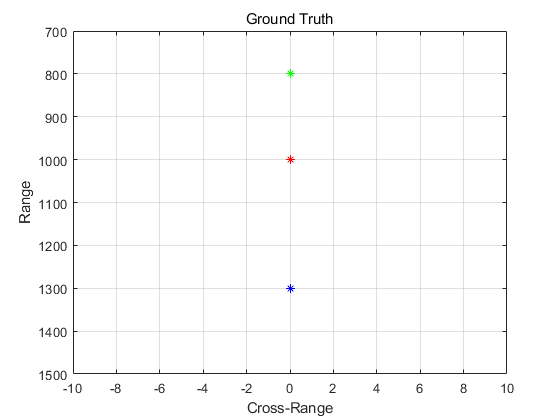

targetpos= [800,0,0;1000,0,0; 1300,0,0]';                                               %设置三个目标的XYZ坐标
targetvel = [0,0,0;0,0,0; 0,0,0]';                                                      %设置三个目标的XYZ速度
target = phased.RadarTarget('OperatingFrequency', fc, 'MeanRCS', [1,1,1]);              %设置目标的RCS

pointTargets = phased.Platform('InitialPosition', targetpos,'Velocity',targetvel);      %初始化目标位置以及目标速度

%   可视化地面实况的目标位置信息
figure(1);
h = axes;plot(targetpos(2,1),targetpos(1,1),'*g');hold all;
plot(targetpos(2,2),targetpos(1,2),'*r');hold all;
plot(targetpos(2,3),targetpos(1,3),'*b');hold off;grid on 

set(h,'Ydir','reverse');xlim([-10 10]);ylim([700 1500]);
title('Ground Truth');ylabel('Range');xlabel('Cross-Range');

## SAR信号仿真

后续场景用于描述基于上述参数后的系统运行仿真，尤其是展示数据如何在SAR平台上采集的章节。随着平台沿着横向距离方向运动，脉冲在正交于横向距离的距离方向上进行发射及接收。当平台运动时，采集到的脉冲能够获取目标在照射区域时间内的相位历史。由于对整个图像的距离和横向距离进行了聚焦，因此目标在光照区域的时间越长，整个图像的横向距离分辨率越好。

%   定义宽边角
refangle = zeros(1,size(targetpos,2));
rxsig = zeros(truncrangesamples,numpulses);

%   开始仿真流程
for ii = 1:numpulses
    %   更新雷达平台和目标位置
    [radarpos, radarvel] = radarPlatform(slowTime);
    [targetpos,targetvel] = pointTargets(slowTime);
    
    %   获取距离和对应目标点的角度
    [targetRange, targetAngle] = rangeangle(targetpos, radarpos);
    
    %   生成LFM脉冲信号
    sig = waveform();
    
    %   只使用最大探测距离的PRT时间对应的发射采样点数
    sig = sig(1:truncrangesamples);
    
    %   发射脉冲信号(信号穿过发射机)
    sig = transmitter(sig);
    
    %   定义在方位方向上无倾斜
    targetAngle(1,:) = refangle;
    
    %   向目标发射脉冲,按照cosine天线的增益调节幅度
    sig = radiator(sig, targetAngle);
    
    %   电磁波命中目标以及反射回来的空间信道传播
    sig = channel(sig, radarpos, targetpos, radarvel, targetvel);
    
    %   目标反射电磁波
    sig = target(sig);
    
    % 接收天线获取反射脉冲信号，三路信号按照天线方向图合成一路
    sig = collector(sig, targetAngle);
    
    %   接收机采样存储数据 
    rxsig(:,ii) = receiver(sig);
    
    %-------------------------------------------
    %   可视化雷达与目标的位置信息
    %-------------------------------------------
%     if rem(ii,100)==0
%         figure(3)
%         plot3(radarpos(1),radarpos(2),radarpos(3),'bo',...
%               targetpos(1,2),targetpos(2,2),targetpos(3,2),'x',...
%               targetpos(1,2),targetpos(2,2),targetpos(3,2),'x',...
%               targetpos(1,2),targetpos(2,2),targetpos(3,2),'x')
%         grid on;hold on
%         title(num2str(ii))
%         axis([0 1200 -300 300 0 600])
%         drawnow
%     end
end

Visualize the received signal.

可视化接收信号

The received signal can now be visualized as a collection of multiple pulses transmitted in the cross-range direction. 

The plots show the real part of the signal for the three targets. 

The range and cross-range chirps can be seen clearly. 

The target responses can be seen as overlapping as the pulse-width is kept longer to maintain average power.

接收到的信号现在可以看作是在交叉距离方向上发射的多个脉冲的集合。

图中显示了三个目标信号的实部。

距离(垂直飞行方向)和横向(飞行方向)的chrip信号可以清楚地看到。目标响应是重叠的原因是脉宽持续时间较长，这样做的目的是保证一定的平均功率，提高信噪比。

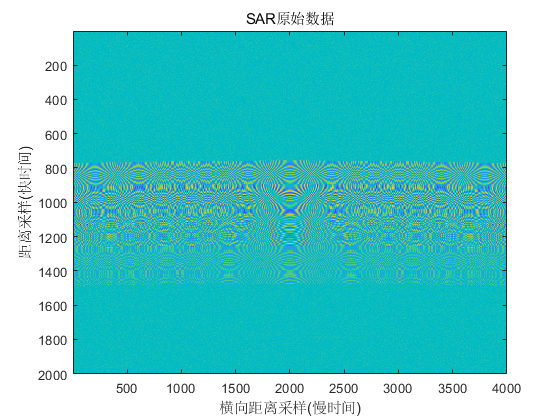

figure(2)
imagesc(real(rxsig));title('SAR原始数据')
xlabel('横向距离采样(慢时间)')
ylabel('距离采样(快时间)')

对距离向使用脉冲压缩

每一列的回波数据，包含了单次脉冲发射的所有信息，可以通过匹配滤波器(解chirp信号)得到脉冲压缩后的信号

%   生成匹配滤波器
pulseCompression = phased.RangeResponse('RangeMethod', ...
                                        'Matched filter',...
                                        'PropagationSpeed', c,...
                                        'SampleRate', fs);
matchingCoeff = getMatchedFilter(waveform);                                     %脉压因子
[cdata, rnggrid] = pulseCompression(rxsig, matchingCoeff);                      %脉冲压缩

下图展示了为接收信号经过匹配滤波器之后的响应。三个目标在横向距离方向上的相位变化历史记录清晰可见，实现了距离向的聚焦。

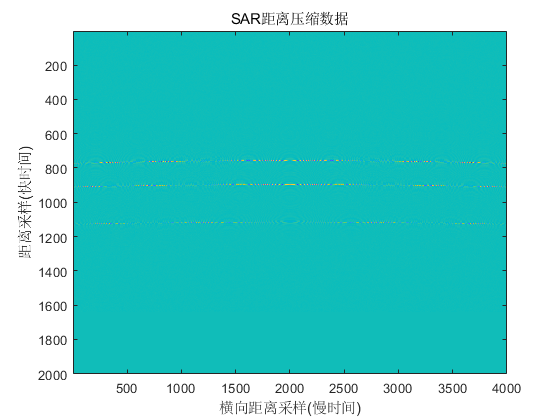

figure(3);
imagesc(real(cdata));title('SAR距离压缩数据')
xlabel('横向距离采样(慢时间)')
ylabel('距离采样(快时间)')

方位压缩

有多种技术手段用来处理横向距离数据，并在完成距离向脉压后从SAR原始数据中获得最终的图像。实际上，脉压有助于在距离向上提高分辨率，在横向距离方向是通过 方位角 或者 横向距离压缩实现的。两种这样的技术是通过距离徙动算法和反向投影算法

rma_processed = helperRangeMigration(cdata,fastTime,fc,fs,prf,speed,numpulses,c,Rc);
bpa_processed = helperBackProjection(cdata,rnggrid,fastTime,fc,fs,prf,speed,crossRangeResolution,c);

可视化最终SAR图像

画出聚焦后的SAR图像采用距离徙动算法和后向传播算法。距离徙动算法只显示图像的一部分已凸显目标的位置。文献[2]和[3]所示的反投影算法和距离徙动算法提供了横向和纵向的理论分辨率的精确数学表达形式。由于所采用的反投影是近似形式，因此反投影时方位角方向上的能量扩散很明显，而距离徙动算法处理的数据表明，达到了理论分辨率的要求。

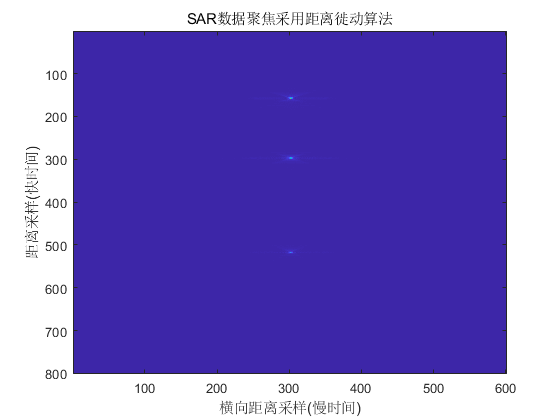

figure(4);
imagesc((abs((rma_processed(1700:2300,600:1400).'))));
title('SAR数据聚焦采用距离徙动算法')
xlabel('横向距离采样(慢时间)')
ylabel('距离采样(快时间)')

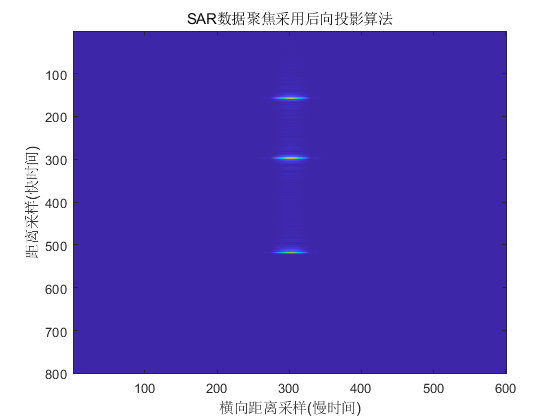

figure(5)
imagesc((abs(bpa_processed(600:1400,1700:2300))));
title('SAR数据聚焦采用后向投影算法')
xlabel('横向距离采样(慢时间)')
ylabel('距离采样(快时间)')

## 总结

本例子展示了如何在机载数据收集场景中利用LFM信号设计SAR信号处理流程。该例子还展示了根据后向散射算法模型 如何通过距离徙动和近似方法从接收信号生成图像。

## 参考文献

- Cafforio, C., Prati, C. and Rocca, F., 1991. SAR data focusing using seismic migration techniques. IEEE transactions on aerospace and electronic systems, 27(2), pp.194-207.

- Cumming, I., Bennett, J., 1979. Digital Processing of Seasat SAR data. IEEE International Conference on Acoustics, Speech, and Signal Processing.

- Na Y., Lu Y., Sun H.,A Comparison of Back-Projection and Range Migration Algorithms for Ultra-Wideband SAR Imaging, Fourth IEEE Workshop on Sensor Array and Multichannel Processing, 2006., Waltham, MA, 2006, pp. 320-324.

- Yegulalp, A.F., 1999. Fast backprojection algorithm for synthetic aperture radar. Proceedings of the 1999 IEEE Radar Conference.

## 附件

Range Migration Algorithm 

距离徙动算法

该函数演示了用于侧视合成孔径雷达成像的距离偏移算法。该算法考虑了脉冲压缩合成孔径数据。

function azcompresseddata = helperRangeMigration(sigData,fastTime,fc,fs,prf,speed,numPulses,c,Rc)
%设置量程频率范围
frequencyRange = linspace(fc-fs/2,fc+fs/2,length(fastTime));
krange = 2*(2*pi*frequencyRange)/c;

Set the cross-range wavenumber.

kaz = 2*pi*linspace(-prf/2,prf/2,numPulses)./speed;

Generate a matrix of the cross-range wavenumbers to match the size of the received two-dimensional SAR signal

kazimuth = kaz.';
kx = krange.^2-kazimuth.^2;

Set the final wavenumber to achieve azimuth focusing.

kx = sqrt(kx.*(kx > 0));
kFinal = exp(1i*kx.*Rc);

Perform a two-dimensional FFT on the range compressed signal.

sdata =fftshift(fft(fftshift(fft(sigData,[],1),1),[],2),2);

Perform bulk compression to get the azimuth compression at the reference range. Perform filtering of the 2-D FFT signal with the new cross-range wavenumber to achieve complete focusing at the reference range and as a by-product, partial focusing of targets not lying at the reference range.

fsmPol = (sdata.').*kFinal;

Perform Stolt Interpolation to achieve focusing for targets that are not lying at the reference range

stoltPol = fsmPol;
for i = 1:size((fsmPol),1)
    stoltPol(i,:) = interp1(kx(i,:),fsmPol(i,:),krange(1,:));
end
stoltPol(isnan(stoltPol)) = 1e-30;
stoltPol = stoltPol.*exp(-1i*krange.*Rc);
azcompresseddata = ifft2(stoltPol);
end

Back-Projection Algorithm

function data = helperBackProjection(sigdata,rnggrid,fastTime,fc,fs,prf,speed,crossRangeResolution,c)

This function demonstrates the time-domain back projection algorithm for imaging the side-looking synthetic aperture radar. The pulsed compressed synthetic aperture data is taken as input in this algorithm. Initialize the output matrix.

data = zeros(size(sigdata));
azimuthDist = -200:speed/prf:200;%azimuth distance

Limit the range and cross-range pixels being processed to reduce processing time.

rangelims = [700 1400];
crossrangelims = [-10 10];

Index the range grid in accordance with the range limits.

rangeIdx =  [find(rnggrid>rangelims(1), 1) find(rnggrid<rangelims(2),1,'last')];

Index the azimuth distance in accordance with the cross-range limits.

crossrangeIdxStart = find(azimuthDist>crossrangelims(1),1);
crossrangeIdxStop = find(azimuthDist<crossrangelims(2),1,'last');
for i= rangeIdx(1):rangeIdx(2)  % Iterate over the range indices
    
    % Using desired cross-range resolution, compute the synthetic aperture
    % length
    lsynth= (c/fc)* (c*fastTime(i)/2)/(2*crossRangeResolution);
    lsar = round(lsynth*length(azimuthDist)/azimuthDist(end)) ;
    % Ensure lsar is an odd number
    lsar = lsar + mod(lsar,2);    
    
    % Construct hanning window for cross-range processing, to suppress the
    % azimuthal side lobes
    hn= hanning(lsar).';
    % Iterate over the cross-range indices
    for j= crossrangeIdxStart:crossrangeIdxStop 
        % azimuth distance in x direction over cross-range indices
        posx= azimuthDist(j);
        % range in y-direction over range indices
        posy= c*fastTime(i)/2;
        % initializing count to zero
        count= 0;
        % Iterate over the synthetic aperture
        for k= j-lsar/2 +1:j+ lsar/2 
            % Time delay for each of range and cross-range indices
            td= sqrt((azimuthDist(k)- posx)^2 + posy^2)*2/c;
            cell= round(td*fs) +1 ;
            signal = sigdata(cell,k);
            count= count + hn(k -(j-lsar/2))*signal *exp(1j*2*pi*fc*(td));
        end
        % Processed data at each of range and cross-range indices
        data(i,j)= count;
    end
    
end
end

*Copyright 2018 The MathWorks, Inc.*